# Plot Electricity Usage

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

usage = table2array(readtable("../data/electricityData.xlsx", "Sheet", "usage", "NumHeaderLines", 0));
dates = table2array(readtable("../data/electricityData.xlsx", "Sheet", "dates", "NumHeaderLines", 0));
sectors = table2array(readtable("../data/electricityData.xlsx", "Sheet", "sectors", "ReadVariableNames", false));
whos

  Name           Size            Bytes  Class       Attributes

  dates        315x1              2542  datetime              
  sectors        1x4               488  cell                  
  usage        315x4             10080  double                



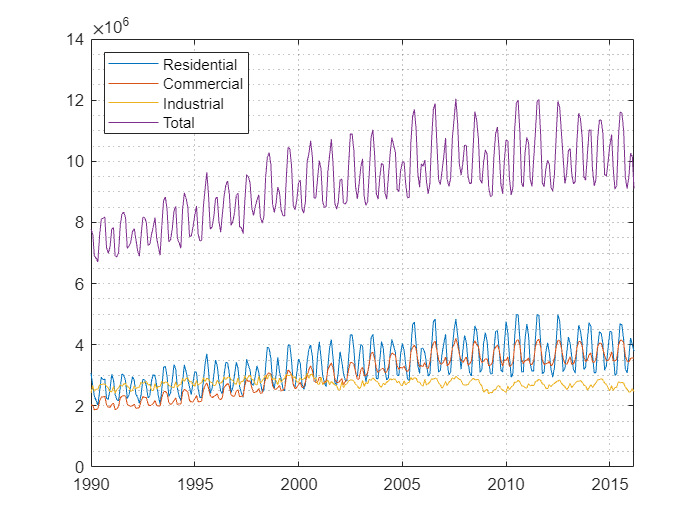

plot(dates, usage)
grid minor
legend(sectors, "Location", "northwest")

## Task 1

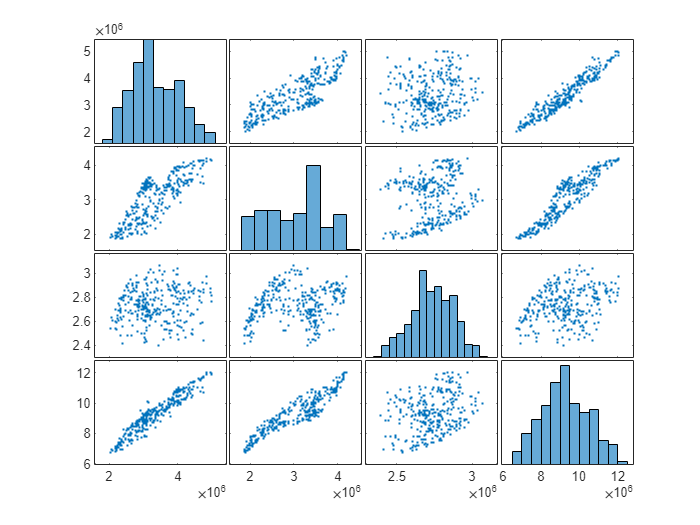

plotmatrix(usage)
grid minor

## Task 2

usagecorr = corrcoef(usage)

usagecorr =     1.0000    0.8243    0.1300    0.9519
    0.8243    1.0000    0.1591    0.9268
    0.1300    0.1591    1.0000    0.2938
    0.9519    0.9268    0.2938    1.0000
